% loading dataset
T = readtable("airbnbPricing.xlsx", "Sheet","Sheet1", "ReadVariableNames",true);

namecols = T.Properties.VariableNames; % column names

% few rows of data
head(T);

    PRICE    DIST    RATE
    _____    ____    ____

     238     4.06    4.6 
     138     9.53    4.7 
     134     7.45    3.6 
     175     6.19      4 
     243     1.98    3.7 
     233     1.98    4.8 
     251     1.05    4.4 
     156     8.73      4 



### Multiple Linear Regression Models

Two Univariate regressions:

% first regression model
model1 = fitlm(T, "PRICE ~ DIST");

% second regression model
model2 = fitlm(T, "PRICE ~ RATE");

Plotting the two models

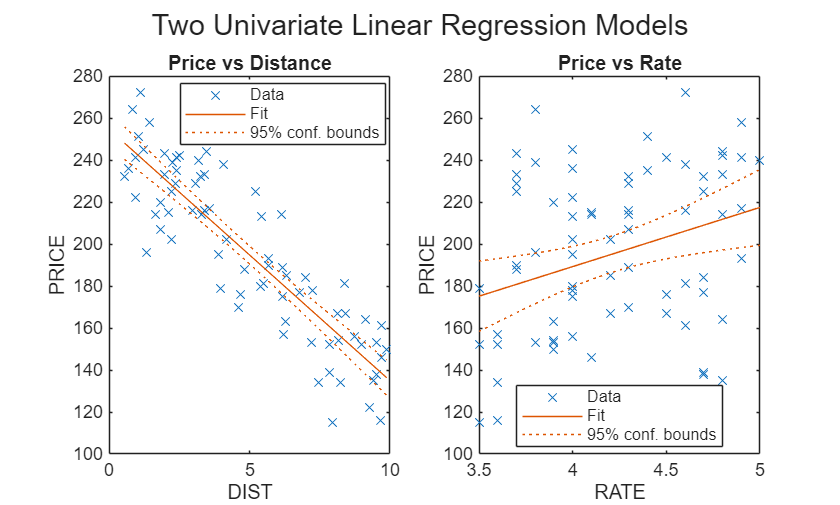

nr = 1; nc = 2; % no of rows and columns

subplot(nr, nc, 1);
plot(model1);
title('Price vs Distance');
xlabel('DIST');
ylabel('PRICE');

subplot(nr, nc, 2);
plot(model2);
title('Price vs Rate');
xlabel('RATE');
ylabel('PRICE');
sgtitle('Two Univariate Linear Regression Models');

### Multi-Regression Model

modelSpec = 'PRICE ~ DIST + RATE';

mdl = fitlm(T, modelSpec);

% Display the summary of the multiple regression model
disp(mdl);


Linear regression model:
    PRICE ~ 1 + DIST + RATE

Estimated Coefficients:
                   Estimate      SE       tStat       pValue  
                   ________    ______    _______    __________

    (Intercept)     177.06     20.041     8.8346    4.2458e-13
    DIST           -11.625     0.6808    -17.075    5.0306e-27
    RATE            18.008     4.5622     3.9474    0.00018193


Number of observations: 75, Error degrees of freedom: 72
Root Mean Squared Error: 16.9
R-squared: 0.821,  Adjusted R-Squared: 0.816
F-statistic vs. constant model: 165, p-value = 1.25e-27


Partial regression coefficient via residual regression (DIST net of RATE)

- Estimate of beta_DIST with univariate regression through the origin

inputRes = model2.Residuals.Raw; % input residuals

model3 = fitlm(T, "DIST ~ RATE"); % DIST from RATE

outputRes = model3.Residuals.Raw; % output residuals

VarNames=["Output residuals" "Input residuals"];

mdlSimpleRegression=fitlm(outputRes, inputRes,'linear','VarNames',VarNames,'Intercept',false);

% model summary
disp(mdlSimpleRegression);


Linear regression model:
    Input residuals ~ Output residuals

Estimated Coefficients:
                        Estimate      SE        tStat       pValue  
                        ________    _______    _______    __________

    Output residuals    -11.625     0.67153    -17.311    9.8291e-28


Number of observations: 75, Error degrees of freedom: 74
Root Mean Squared Error: 16.6


### Partial Correlation Matrix

TX = table2array(T); % values in a matrix

% partial corr matrix
Rp = partialcorr(TX);

% convert partial corr matrix to a table
RpTable = array2table(Rp, 'VariableNames', namecols, 'RowNames', namecols);
disp(RpTable);

              PRICE        DIST       RATE  
             ________    ________    _______

    PRICE           1    -0.89552    0.42179
    DIST     -0.89552           1      0.325
    RATE      0.42179       0.325          1



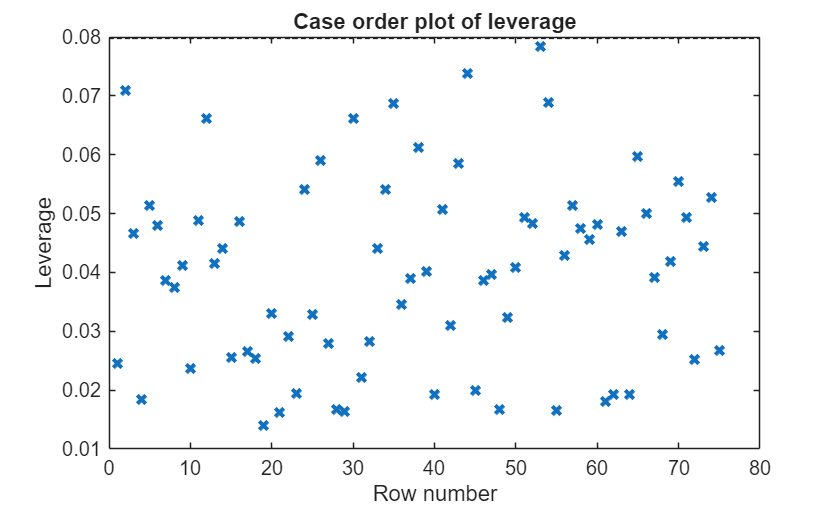

% Analysis of leverage points
figure
h=plotDiagnostics(mdl,"leverage","LineWidth",2);
h(2).LineWidth=2;

Scatter of ASSOR agaoinst PROMO

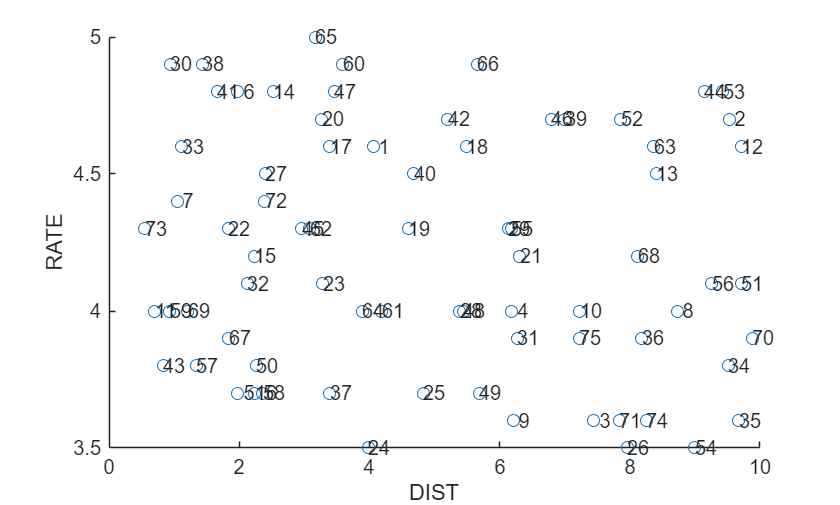

figure
n=size(T,1);

scatter(T,"DIST","RATE");
text(T.DIST,T.RATE,num2str((1:n)'));

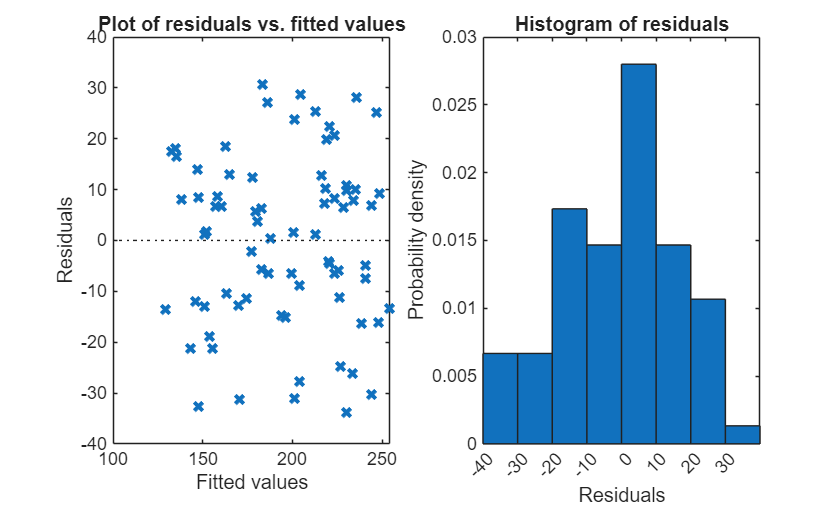

subplot(1, 2, 1);
plotResiduals(mdl, "fitted", "ResidualType", "raw", "LineWidth", 2);

subplot(1, 2, 2);
plotResiduals(mdl, "histogram");

x0 = [2.5 4.6];

% prediction
[y_hat0, y_hat_pi] = predict(mdl, x0, 'Alpha', 0.01);

disp("Predicted Price for the house, Distance=2.5 KM and Avg Ratings=4.6 is => €" + num2str(y_hat0));

Predicted Price for the house, Distance=2.5 KM and Avg Ratings=4.6 is => €230.8348
